# **Matlab案例代码解析**

## 4. 图像信号处理案例

### 4.1 滤波

#### 4.1.6 卡尔曼滤波

参考文献：

[https://www.cs.unc.edu/~welch/media/pdf/kalman_intro.pdf](https://www.cs.unc.edu/~welch/media/pdf/kalman_intro.pdf)

[https://www.cs.unc.edu/~welch/kalman/media/pdf/kalman_intro_chinese.pdf](https://www.cs.unc.edu/~welch/kalman/media/pdf/kalman_intro_chinese.pdf)

[http://www.bzarg.com/p/how-a-kalman-filter-works-in-pictures/](http://www.bzarg.com/p/how-a-kalman-filter-works-in-pictures/)

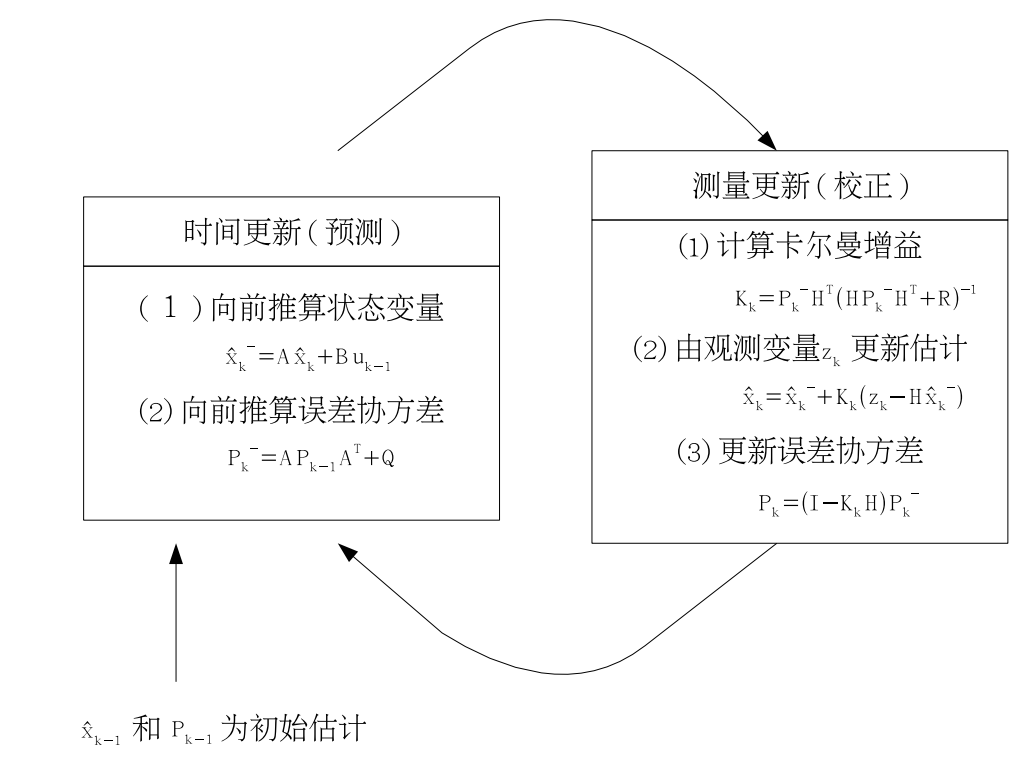

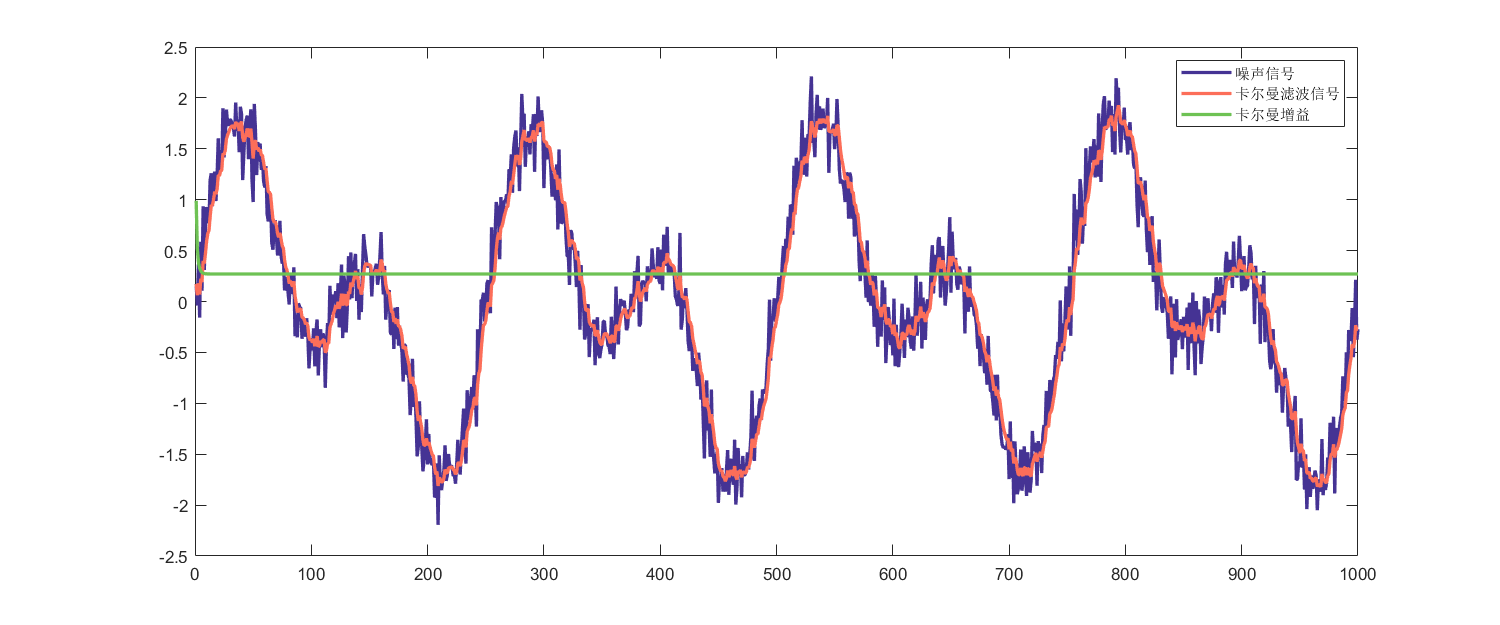

clear;clc;
[all_themes, all_colors] = GetColors();
load noisbloc;
load noisbump;
load noisdopp;
load leleccum;
signal = noisbloc;
len = 1000;
t = linspace(0, 8*pi, len);
signal = sin(t) + sin(2*t) + 0.2 * randn(1, len);
len = length(signal);
fsignal = zeros(1, len);
% 根据图片来
x = 0;
A = 1;
B = 0;
H = 1;
P = 1;
Q = 0.001;
R = 0.01;
K = 0;

Ks =zeros(1, len);
for i = 1 : len
    % 时间更新
    x = A * x + B * signal(i);
    P = A * P * A + Q;
    % 测量更新
    K = P * H /(H * P * H + R);
    x = x + K * (signal(i) - H * x);
    P = (1 - K * H) * P;
    % 结果
    fsignal(i) = x;
    Ks(i) = K;
end
figure('Position', [10, 10, 1200, 500]);
plot(signal, 'LineWidth', 2, 'Color', all_colors(6, :));
hold on
plot(fsignal, 'LineWidth', 2, 'Color', all_colors(1, :));
plot(Ks, 'LineWidth', 2, 'Color', all_colors(3, :));
hold off
legend('噪声信号', '卡尔曼滤波信号', '卡尔曼增益');